# External flow analysis

## Import the data

### Import interface flow data

interfaceFlow = importInterfaceFlow("D:\EERL\2019_NYISO\2019_Interface_Flow\20190101ExternalLimitsFlows.csv")

interfaceFlow = 5202×6 table
       Timestamp            InterfaceName         PointID    FlowMWH    PositiveLimitMWH    NegativeLimitMWH
    ________________    ______________________    _______    _______    ________________    ________________

    01/01/2019 00:00    CENTRAL EAST - VC         23330       2285.9          2425               -9999      
    01/01/2019 00:00    DYSINGER EAST             23326        943.6          3150               -9999      
    01/01/2019 00:00    MOSES SOUTH               23319         1263          3150               -1600      
    01/01/2019 00:00    SCH - HQ - NY             23324          375          1500               -1000      
    01/01/2019 00:00    SCH - HQ_CEDARS           325274           0           199                -100      
   

#### list of interface

Import/Export proxy (11);

HQ Proxy (3): HQCD (Cedars), HQEX (Import_Export), HQNY (Chateauguay),

NPX Proxy (3): NENP (1385 Northport), NPX-AC (NE-NY), NPX-CSC,

OH Proxy (1): OH-AC, 

PJM Proxy (4): PJDF (Neptune), PJM-AC (PJ-NY, Keystone), PJM-HTP (Hudsuon TP), PJM-VFT (Linden VFT)

groupsummary(interfaceFlow, "InterfaceName")

ans = 18×2 table
        InterfaceName         GroupCount
    ______________________    __________

    CENTRAL EAST - VC            289    
    DYSINGER EAST                289    
    MOSES SOUTH                  289    
    SCH - HQ - NY                289    
    SCH - HQ_CEDARS              289    
    SCH - HQ_IMPORT_EXPORT       289    
    SCH - NE - NY                289    
    SCH - NPX_1385               289    
    SCH - NPX_CSC                289    
    SCH - OH - NY                289    
    SCH - PJ - NY                289    
    SCH - PJM_HTP                289    
    SCH - PJM_NEPTUNE            289    
    SCH - PJM_VFT                289    
    SPR/DUN-SOUTH                289    
    TOTAL EAST                   289    


interfaceNames = unique(interfaceFlow.InterfaceName);
externalIdx = startsWith(string(interfaceNames), "SCH - ");
externalFlowNames = interfaceNames(externalIdx)

externalFlowNames = 11×1 categorical array
     SCH - HQ - NY 
     SCH - HQ_CEDARS 
     SCH - HQ_IMPORT_EXPORT 
     SCH - NE - NY 
     SCH - NPX_1385 
     SCH - NPX_CSC 
     SCH - OH - NY 
     SCH - PJ - NY 
     SCH - PJM_HTP 
     SCH - PJM_NEPTUNE 
     SCH - PJM_VFT 


internalFlowNames = interfaceNames(~externalIdx)

internalFlowNames = 7×1 categorical array
     CENTRAL EAST - VC 
     DYSINGER EAST 
     MOSES SOUTH 
     SPR/DUN-SOUTH 
     TOTAL EAST 
     UPNY CONED 
     WEST CENTRAL 


### Import Energy components data

energyFileDir = "D:\EERL\2019_NYISO\2019_Daily_Energy\";
energyFileName = "2019*";
energyDataStore = fileDatastore(energyFileDir + energyFileName, "ReadFcn", @importTotalEnergy, "UniformRead", true);
energyAll = readall(energyDataStore);
clear energyDataStore;

externalEnergyAll = energyAll(:, ["TimeStamp","NetImportsDNIOH","NetImportsDNIHQ","NetImportsDNINPX","NetImportsDNIPJM","NetImportsNYISO"])

externalEnergyAll = 8016×6 table
       TimeStamp        NetImportsDNIOH    NetImportsDNIHQ    NetImportsDNINPX    NetImportsDNIPJM    NetImportsNYISO
    ________________    _______________    _______________    ________________    ________________    _______________

    01/01/2019 00:00         1104                466                -214                593                1949      
    01/01/2019 01:00         1112                369                -342                452                1591      
    01/01/2019 02:00         1058                345                -477                288                1214      
    01/01/2019 03:00         1054                345                -614                208                 993      
    01/01/2019 04:00          973                345  

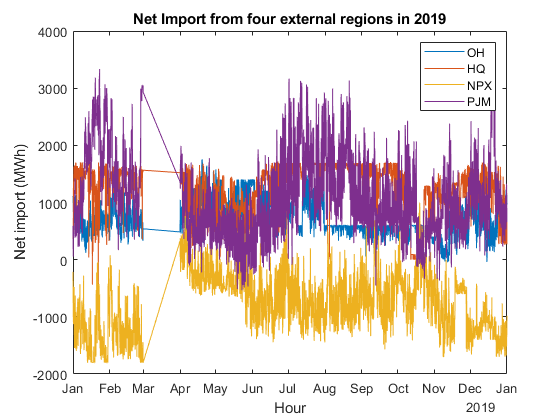

plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIOH);
hold on;
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIHQ);
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNINPX);
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIPJM);
hold off;
xlabel("Hour");
ylabel("Net import (MWh)");
title("Net Import from four external regions in 2019");
legend(["OH","HQ","NPX","PJM"]);

### Daily and monthly summary

externalDailySum = groupsummary(externalEnergyAll,"TimeStamp","day","sum",["NetImportsDNIHQ","NetImportsDNINPX","NetImportsDNIOH","NetImportsDNIPJM","NetImportsNYISO"]);
externalMonthlySum = groupsummary(externalEnergyAll,"TimeStamp","month","sum",["NetImportsDNIHQ","NetImportsDNINPX","NetImportsDNIOH","NetImportsDNIPJM","NetImportsNYISO"]);

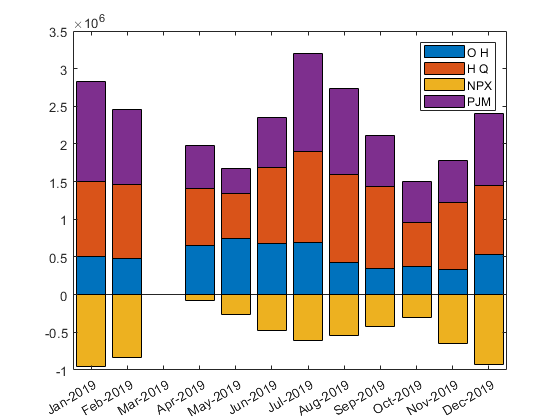

figure;
y = [externalMonthlySum.sum_NetImportsDNIOH, externalMonthlySum.sum_NetImportsDNIHQ, externalMonthlySum.sum_NetImportsDNINPX, externalMonthlySum.sum_NetImportsDNIPJM];
bar(externalMonthlySum.month_TimeStamp, y, 'stacked');
legend(["O H","H Q","NPX","PJM"])

### Import DAM zonal price data

priceFileDir = "D:\EERL\2019_NYISO\2019_DAM_LBMP_Zonal\";
priceFileName = "2019*";
energyDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importZonalPrice, "UniformRead", true);
priceAll = readall(energyDataStore);
clear priceDataStore;
priceAll

priceAll = 131400×6 table
       TimeStamp        ZoneName    PTID     LBMP     MarginalCostLosses    MarginalCostCongestion
    ________________    ________    _____    _____    __________________    ______________________

    01/01/2019 00:00     CAPITL     61757     26.4           0.73                   -15.32        
    01/01/2019 00:00     CENTRL     61754    12.31           0.02                    -1.95        
    01/01/2019 00:00     DUNWOD     61760    23.24           0.94                   -11.96        
    01/01/2019 00:00     GENESE     61753    11.39          -0.37                    -1.43        
    01/01/2019 00:00     H Q        61844    10.09          -0.25                        0        
    01/01/2019 00:00     HUD VL     61758    22.47           0.85           

#### Price data cleaning

- 03/10/2019 02:00 data is missing: linear interpolation.

- 11/03/2019 01:00 has duplicates: remove the duplicate record.

% Clean missing data
beforeMissingTime = datetime('03/10/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
afterMissingTime = datetime('03/10/2019 03:00:01',"Format","MM/dd/uuuu HH:mm:ss");
priceAllMissing = priceAll(priceAll.TimeStamp >= beforeMissingTime & priceAll.TimeStamp < afterMissingTime | ismissing(priceAll.TimeStamp),:);
priceAllAddMissing = groupsummary(priceAllMissing, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("03/10/2019 02:00:00", 15)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllAddMissing = addvars(priceAllAddMissing, TimeStamp, 'Before', 'ZoneName');
priceAllAddMissing = removevars(priceAllAddMissing, "GroupCount");
priceAllAddMissing.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];

% Clean duplicated data
dupTime = datetime('11/03/2019 01:00:00',"Format","MM/dd/uuuu HH:mm:ss");
priceAllNoDup = priceAll(priceAll.TimeStamp ~= dupTime, :);
priceAllDup = priceAll(priceAll.TimeStamp == dupTime, :);
priceAllRemoveDup = groupsummary(priceAllDup, ["ZoneName","PTID"],"mean",["LBMP","MarginalCostLosses","MarginalCostCongestion"]);
TimeStamp = datetime(repelem("11/03/2019 01:00:00", 15)',"Format","MM/dd/uuuu HH:mm:ss");
priceAllRemoveDup = addvars(priceAllRemoveDup, TimeStamp, 'Before', 'ZoneName');
priceAllRemoveDup = removevars(priceAllRemoveDup, "GroupCount");
priceAllRemoveDup.Properties.VariableNames = ["TimeStamp","ZoneName","PTID","LBMP","MarginalCostLosses","MarginalCostCongestion"];
priceAllCleaned = [priceAllNoDup; priceAllAddMissing; priceAllRemoveDup];
priceAllCleaned = sortrows(priceAllCleaned, "TimeStamp");

externalZones = categorical(["O H","H Q","NPX","PJM"]);
priceExternal = priceAllCleaned(ismember(priceAllCleaned.ZoneName, externalZones), :);
priceOH = priceExternal(priceExternal.ZoneName == "O H", :);
priceHQ = priceExternal(priceExternal.ZoneName == "H Q", :);
priceNPX = priceExternal(priceExternal.ZoneName == "NPX", :);
pricePJM = priceExternal(priceExternal.ZoneName == "PJM", :);

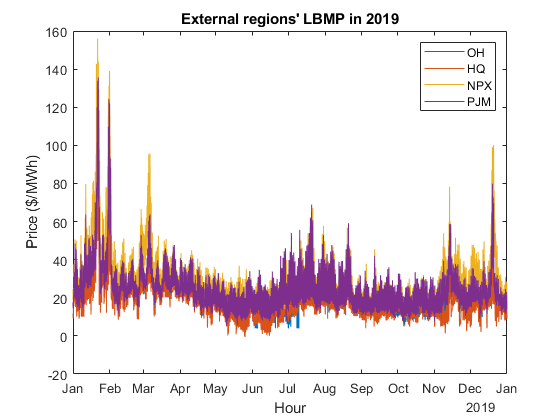

figure;
plot(priceOH.TimeStamp, priceOH.LBMP);
hold on;
plot(priceHQ.TimeStamp, priceHQ.LBMP);
plot(priceNPX.TimeStamp, priceNPX.LBMP);
plot(pricePJM.TimeStamp, pricePJM.LBMP);
hold off;
ylabel("Price ($/MWh)");
xlabel("Hour");
title("External regions' LBMP in 2019");
legend(["OH","HQ","NPX","PJM"]);

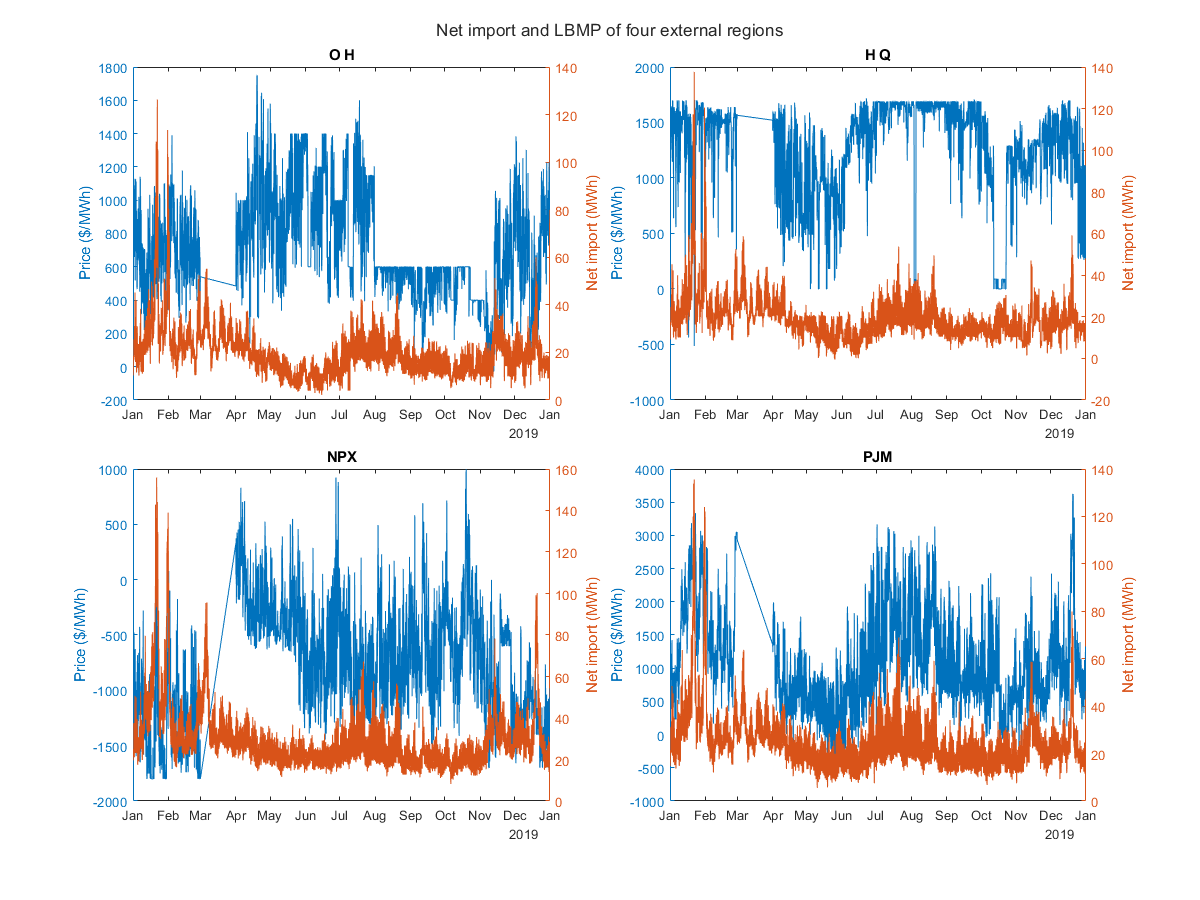

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
nexttile;
yyaxis left;
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIOH);
ylabel("Price ($/MWh)");
yyaxis right;
plot(priceOH.TimeStamp, priceOH.LBMP);
ylabel("Net import (MWh)");
title("O H");

nexttile;
yyaxis left;
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIHQ);
ylabel("Price ($/MWh)");
yyaxis right;
plot(priceHQ.TimeStamp, priceHQ.LBMP);
ylabel("Net import (MWh)");
title("H Q");

nexttile;
yyaxis left;
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNINPX);
ylabel("Price ($/MWh)");
yyaxis right;
plot(priceNPX.TimeStamp, priceNPX.LBMP);
ylabel("Net import (MWh)");
title("NPX");

nexttile;
yyaxis left;
plot(externalEnergyAll.TimeStamp, externalEnergyAll.NetImportsDNIPJM);
ylabel("Price ($/MWh)");
yyaxis right;
plot(pricePJM.TimeStamp, pricePJM.LBMP);
ylabel("Net import (MWh)");
title("PJM");
title(t, "Net import and LBMP of four external regions");
set(gcf, "Position", [100, 100, 1200, 900]);

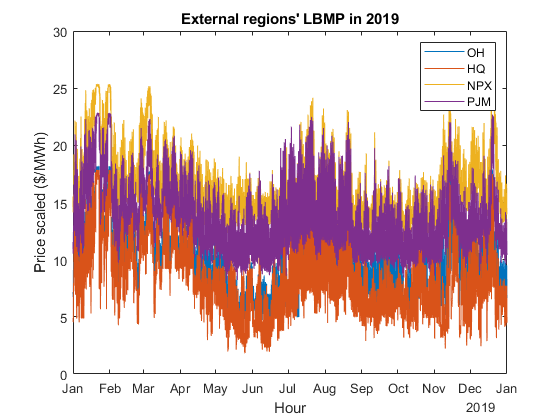

priceOH.Zscore = zscore(priceOH.LBMP);
priceOH.priceScaled = exp(priceOH.Zscore)./(1+exp(priceOH.Zscore)) * (median(priceOH.LBMP) - min(priceOH.LBMP)) + min(priceOH.LBMP);
priceHQ.Zscore = zscore(priceHQ.LBMP);
priceHQ.priceScaled = exp(priceHQ.Zscore)./(1+exp(priceHQ.Zscore)) * (median(priceHQ.LBMP) - min(priceHQ.LBMP)) + min(priceHQ.LBMP);
priceNPX.Zscore = zscore(priceNPX.LBMP);
priceNPX.priceScaled = exp(priceNPX.Zscore)./(1+exp(priceNPX.Zscore)) * (median(priceNPX.LBMP) - min(priceNPX.LBMP)) + min(priceNPX.LBMP);
pricePJM.Zscore = zscore(pricePJM.LBMP);
pricePJM.priceScaled = exp(pricePJM.Zscore)./(1+exp(pricePJM.Zscore)) * (median(pricePJM.LBMP) - min(pricePJM.LBMP)) + min(pricePJM.LBMP);
figure;
plot(priceOH.TimeStamp, priceOH.priceScaled);
hold on;
plot(priceHQ.TimeStamp, priceHQ.priceScaled);
plot(priceNPX.TimeStamp, priceNPX.priceScaled);
plot(pricePJM.TimeStamp, pricePJM.priceScaled);
hold off;
ylabel("Price scaled ($/MWh)");
xlabel("Hour");
title("External regions' LBMP in 2019");
legend(["OH","HQ","NPX","PJM"]);